# **Matisse example for Small lung**

#### **LOADING DATA**

We create a SPOTS1 file that contains the information of one sample

decoded_file = ['E:\Lung\Decoded\decoded_MetricBased_sparse_panel123_small.csv']; % This is the output of our decoding, with csv position
image = ['E:\Lung\First_small_section\Preprocessing\Stitched2DTiles_MIST_Ref1\200901_Lung_test_Round2(2)-Orthogonal Projection-08_c1.tif'];  % this is our example DAPI
scale=1; 
SPOTS1=ISS_getspots(decoded_file,'genecolumn',18,'XYcolumn',[15,16]);
SPOTS1.image=image;
SPOTS1.scale=scale;

And then we combine them into a big object (note that if you have added more samples you need to add them here as well)

ALLSPOTS.SPOTS1=SPOTS1;

### **Format ALLSSPOTS in good format**

We use 'fill_matisse' to format the ALLSPOTS in the SPOTS object. 

SPOTS=fill_matisse(ALLSPOTS);

SPOTS =   matisseMOD with properties:

                                 Graphics: 1
                                 spotname: []
                                 location: []
                                   sample: []
                                   domain: []
                                sample_ID: []
                                   images: []
                                    scale: []
                         expressionmatrix: []
                          expressionnames: []
                              centroidpos: {}
                                 Cellmaps: {}
                               centroidID: {}
            GeneDensity_Genes_of_interest: {}
                    GeneDensity_bandwidth: 300
                     GeneDensity_colormap: [256×3 double]
    OverlayTwoDensities_Genes_of_interest: {}
            OverlayTwoDensities_bandwidth: 300
             OverlayTwoDensities_colormap: [256×3 dou

## **Plotting spots**

In order to plot spots use

SPOTS.location=SPOTS.location.*(6.15);

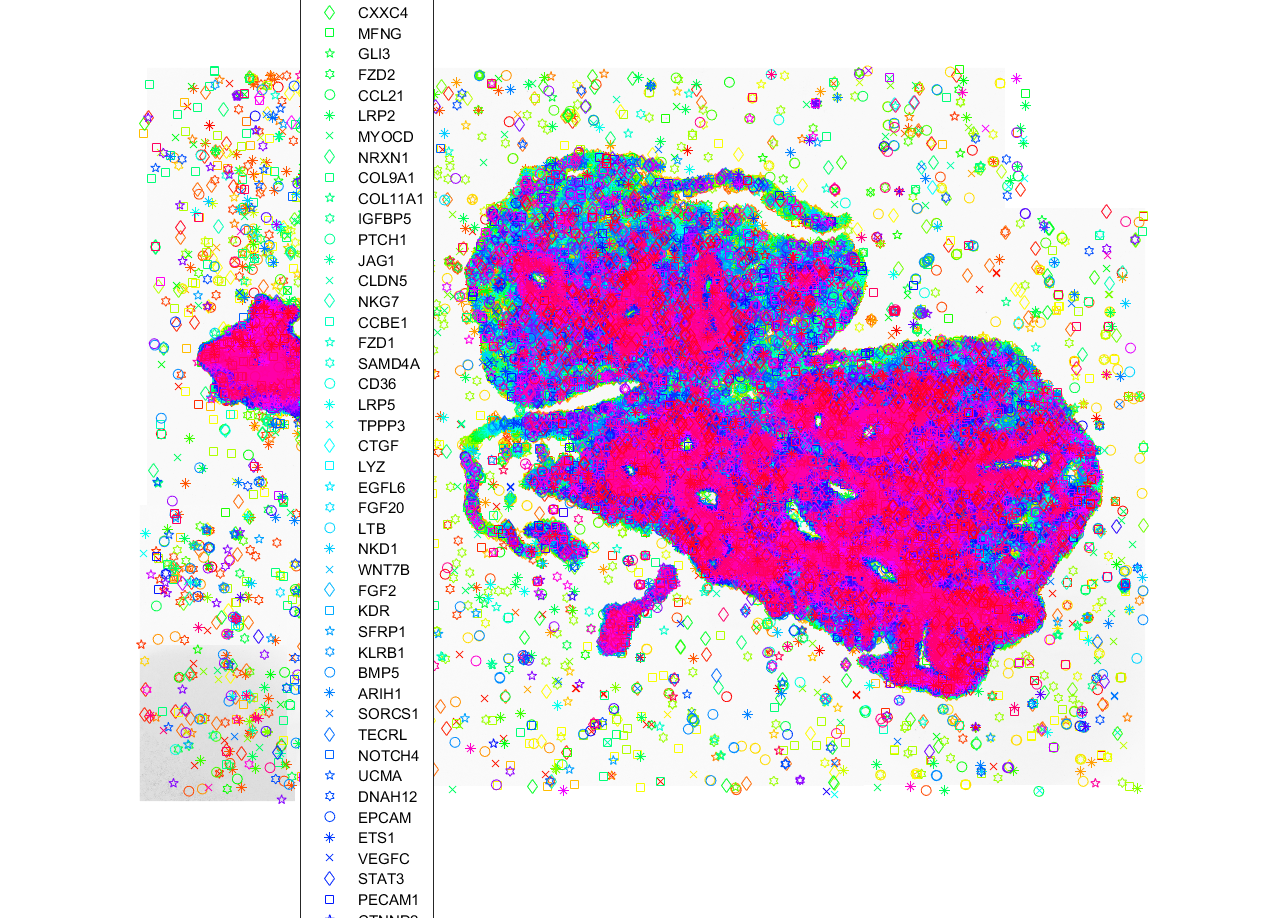


show_spots(SPOTS);

# Work with cells

We then try to work with cells. For this, we fist segment nuclei and then we use the CellMap in the second function callded "define_cells" for creating the cells object

SPOTS.segmentation_percent=83;
[CORTEX_SPOTS2]= DAPI_segmentation(SPOTS);


Loading single cell data for comparison with de novo clustering

path='F:\LUNG_matrixOCT.csv'; % this is a celltypexgene matrix
[SINGLE_CELL]=load_scRNAseq(path);
SINGLE_CELL.expressionmatrix=SINGLE_CELL.expressionmatrix+0.01;
SINGLE_CELL.NC_method='log2';
SINGLE_CELL=Normalize_cells(SINGLE_CELL);


Probabilistic cell typining (PCIseq);

CORTEX_SPOTS2.inefficiency=0.02;
%SINGLE_CELL=cell_subset(SINGLE_CELL);
PCISEQ_CELLS=pciseq(CORTEX_SPOTS2,SINGLE_CELL);

% the object PCISEQ_CELLS contains the output of the probabilistic cell
% typing

We now save the output of this as a table, containinig cellxgene expression, probabilities of every cell and celltype pair, XY position and defined identity of the cells.

TAB=array2table(PCISEQ_CELLS.expressionmatrix);
TAB.Properties.VariableNames=PCISEQ_CELLS.expressionnames;
TAB.name=PCISEQ_CELLS.spotname;
TAB.X=PCISEQ_CELLS.location(:,1);
TAB.Y=PCISEQ_CELLS.location(:,2);

TAB2=array2table(PCISEQ_CELLS.pciseq_probabilities);
TAB2.Properties.VariableNames=PCISEQ_CELLS.pciseq_probabilities_names;

TAB3=horzcat(TAB,TAB2(1:end-1,:));
%TAB4=TAB3(~ismember(TAB3.name,{'Zero'}),:);

writetable(TAB3,'<PATH/FILENAME.csv>');
